# CPA analysis Experiment

import and preprocess data:

load("data.mat");
d = int32(d);
s = int32(s);
wave = int32(wave);

s_box:

for k = 0:255
    for i = 1:1000
        v(i, k+1) = s(bitxor(d(i), k)+1);
    end
end

hamming_weight:

hw = zeros(1000, 256, 'int32');
%1000: D
%256: K
for i = 1:8
    hw = hw + mod(v, 2);
    v = idivide(v, 2);
end

Pearson correlation coefficient:

for i = 1:256 %k+1
    for j = 1:2000 %t+1
        R = corrcoef(double(hw(:, i)), double(wave(:, j)));
        r(i, j) = R(1, 2);
    end
end

The absolute value of r:

r_abs = abs(r);

Find maximum:

[M, I] = max(r_abs, [], "all");
[row, col] = ind2sub(size(r_abs), I);
ck = row-1;
ct = col-1;

Save the result:

save("output_CPA.mat");

Paint:

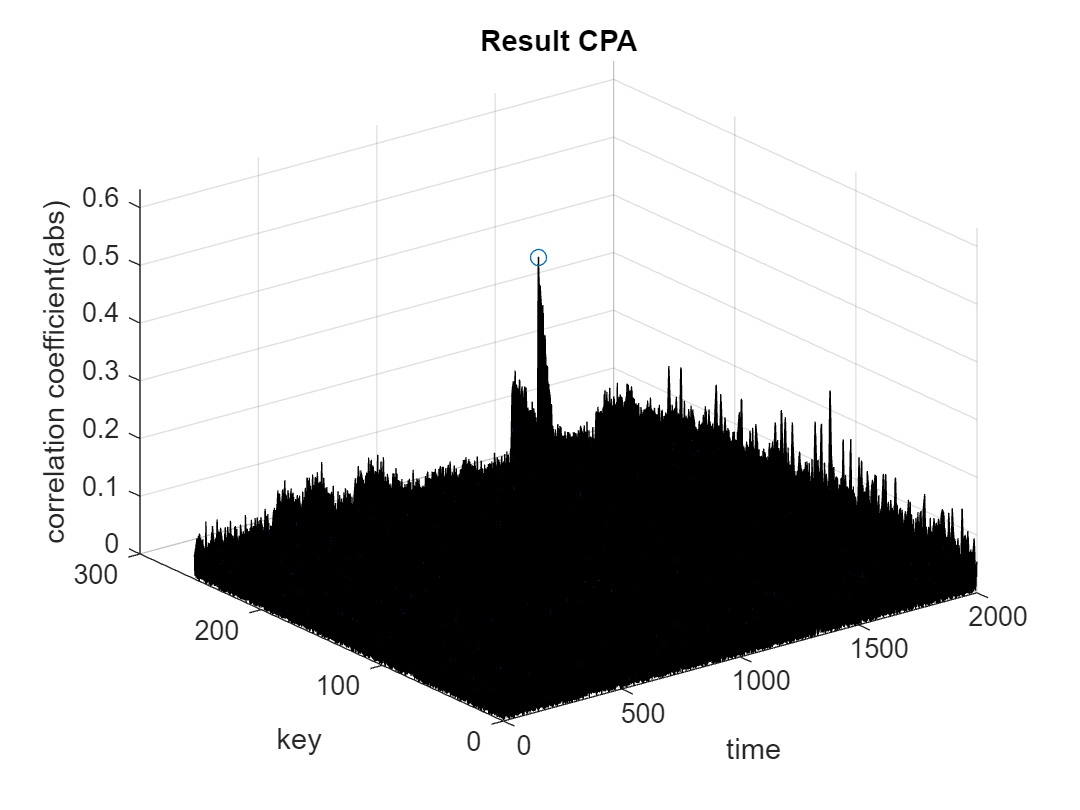

[X, Y] = meshgrid(0:1999, 0:255);
surf(X, Y, r_abs);
hold on;
xlabel('time');
ylabel('key');
zlabel('correlation coefficient(abs)');
title('Result CPA');
hold on;
scatter3(ct, ck, M);
hold off;